# Semantic image segmentation using deep learning

**Goal:** Build and evaluate semantic image segmentation solutions using deep learning architectures. 

**Learning objectives:**

- Learn how to implement an image segmentation workflow in MATLAB

- Learn how to implement and evaluate contemporary (deep-learning-based) semantic image segmentation techniques in MATLAB

- Get acquainted with representative datasets and problems in image segmentation

## Semantic image segmentation using a pretrained network

Main steps:

- Get the labeled data (CamVid dataset).

- Explore, understand, and prepare the data.

- Create network.

- Train network.

- Evaluate results visually (displaying a test image and overlaying predicted labels).

- Evaluate results quantitatively using different metrics (class accuracy, IoU).

- (OPTIONAL) Repeat steps 3 through 6 using different pretrained networks, training options, data augmentation options, and/or metrics. 

Refs: 

[https://www.mathworks.com/help/vision/ug/semantic-segmentation-with-deep-learning.html#mw_44be2a2e-ec6b-4a03-9470-ea945f74515e](https://www.mathworks.com/help/vision/ug/semantic-segmentation-with-deep-learning.html#mw_44be2a2e-ec6b-4a03-9470-ea945f74515e)

[https://www.mathworks.com/help/vision/examples/semantic-segmentation-using-deep-learning.html](https://www.mathworks.com/help/vision/examples/semantic-segmentation-using-deep-learning.html)

### **Example code**

#### Step 1: Get the labeled data (CamVid dataset).

**Download dataset (CamVid)**

Download the CamVid image data (images and labels) from the URL provided via Canvas.

Organize your working folder by creating a `CamVid` folder, which should contain two subfolders (where the files downloaded in the previous step should be placed), called `images` and `labels`, and setting the `outputFolder` variable accordingly, as shown below. 

outputFolder = fullfile('./CamVid/');
imageDir = fullfile(outputFolder,'images');
labelDir = fullfile(outputFolder,'labels');

**Load CamVid data**

The CamVid data set encodes the pixel labels as RGB images, where each class is represented by an RGB color. Here are the classes the dataset defines along with their RGB encodings.

classNames = [ ...
    "Animal", ...
    "Archway", ...
    "Bicyclist", ...
    "Bridge", ...
    "Building", ...
    "Car", ...
    "CartLuggagePram", ...
    "Child", ...
    "Column_Pole", ...
    "Fence", ...
    "LaneMkgsDriv", ...
    "LaneMkgsNonDriv", ...
    "Misc_Text", ...
    "MotorcycleScooter", ...
    "OtherMoving", ...
    "ParkingBlock", ...
    "Pedestrian", ...
    "Road", ...
    "RoadShoulder", ...
    "Sidewalk", ...
    "SignSymbol", ...
    "Sky", ...
    "SUVPickupTruck", ...
    "TrafficCone", ...
    "TrafficLight", ...
    "Train", ...
    "Tree", ...
    "Truck_Bus", ...
    "Tunnel", ...
    "VegetationMisc", ...
    "Wall"];

Define the mapping between label indices and class names such that `classNames(k)` corresponds to `labelIDs(k,:)`.

labelIDs = [ ...
    064 128 064; ... % "Animal"
    192 000 128; ... % "Archway"
    000 128 192; ... % "Bicyclist"
    000 128 064; ... % "Bridge"
    128 000 000; ... % "Building"
    064 000 128; ... % "Car"
    064 000 192; ... % "CartLuggagePram"
    192 128 064; ... % "Child"
    192 192 128; ... % "Column_Pole"
    064 064 128; ... % "Fence"
    128 000 192; ... % "LaneMkgsDriv"
    192 000 064; ... % "LaneMkgsNonDriv"
    128 128 064; ... % "Misc_Text"
    192 000 192; ... % "MotorcycleScooter"
    128 064 064; ... % "OtherMoving"
    064 192 128; ... % "ParkingBlock"
    064 064 000; ... % "Pedestrian"
    128 064 128; ... % "Road"
    128 128 192; ... % "RoadShoulder"
    000 000 192; ... % "Sidewalk"
    192 128 128; ... % "SignSymbol"
    128 128 128; ... % "Sky"
    064 128 192; ... % "SUVPickupTruck"
    000 000 064; ... % "TrafficCone"
    000 064 064; ... % "TrafficLight"
    192 064 128; ... % "Train"
    128 128 000; ... % "Tree"
    192 128 192; ... % "Truck_Bus"
    064 000 064; ... % "Tunnel"
    192 192 000; ... % "VegetationMisc"
    064 192 000];    % "Wall"

Create an `imageDatastore` to load the CamVid images.

imds = imageDatastore(fullfile(imageDir));

Create a `pixelLabelDatastore` to load the CamVid pixel labels.

pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);

#### Step 2: Explore, understand, and prepare the data.

**Explore images and pixel labels**

Read the Mth image and corresponding pixel label image.

M = 15;
I = readimage(imds,M);
C = readimage(pxds,M);

The pixel label image is returned as a categorical array where `C(i,j)` is the categorical label assigned to pixel `I(i,j)`. Display the pixel label image on top of the image.

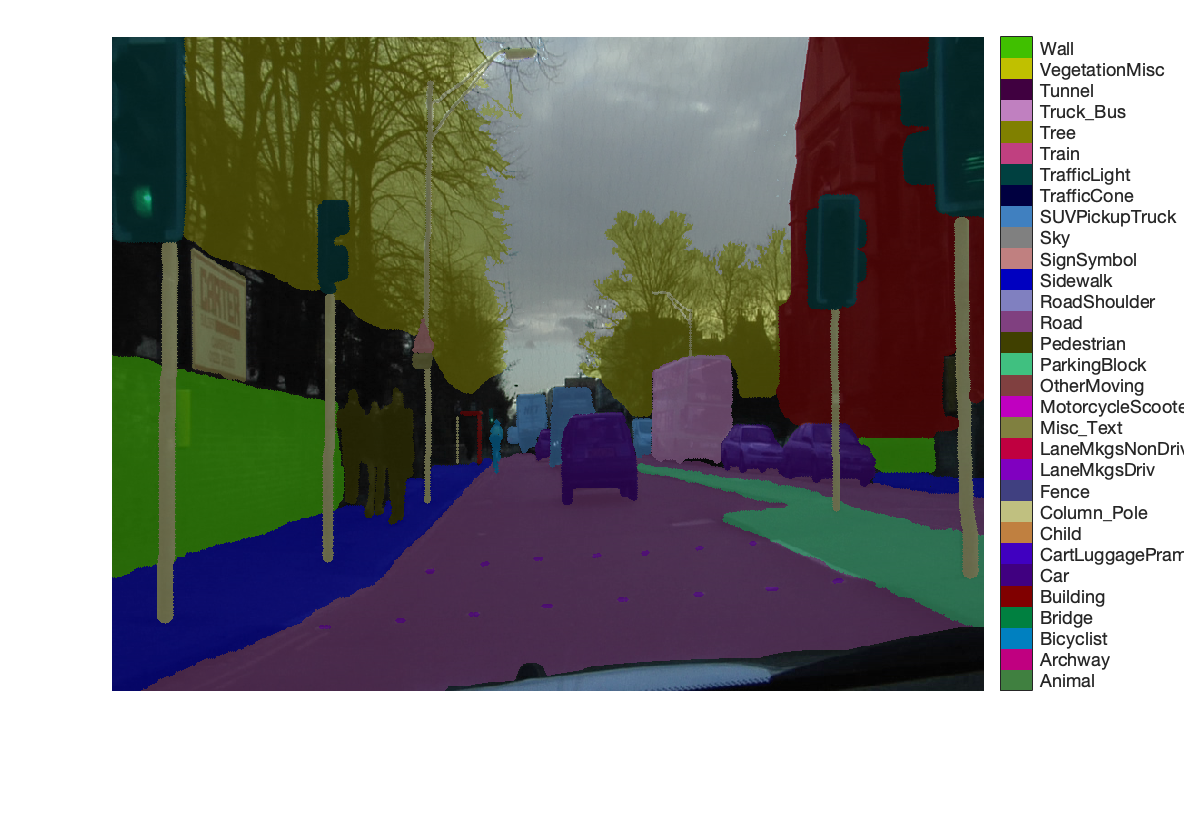

B = labeloverlay(I,C,'Colormap',labelIDs./255);
figure
imshow(B)

% Add a colorbar.
N = numel(classNames);
ticks = 1/(N*2):1/N:1;
colorbar('TickLabels',cellstr(classNames),'Ticks',ticks,'TickLength',0,'TickLabelInterpreter','none');
colormap(labelIDs./255)

**Undefined or Void Labels**

It is common for pixel labeled datasets to include "undefined" or "void" labels. These are used to designate pixels that were not labeled. For example, in CamVid, the label ID [0 0 0] is used to designate the "void" class. Training algorithms and evaluation algorithms are not expected to include these labels in any computations.

The "void" class need not be explicitly named when using `pixelLabelDatastore`. Any label ID that is not mapped to a class name is automatically labeled "undefined" and is excluded from computations. To see the undefined pixels, use `isundefined` to create a mask and then display it on top of the image.

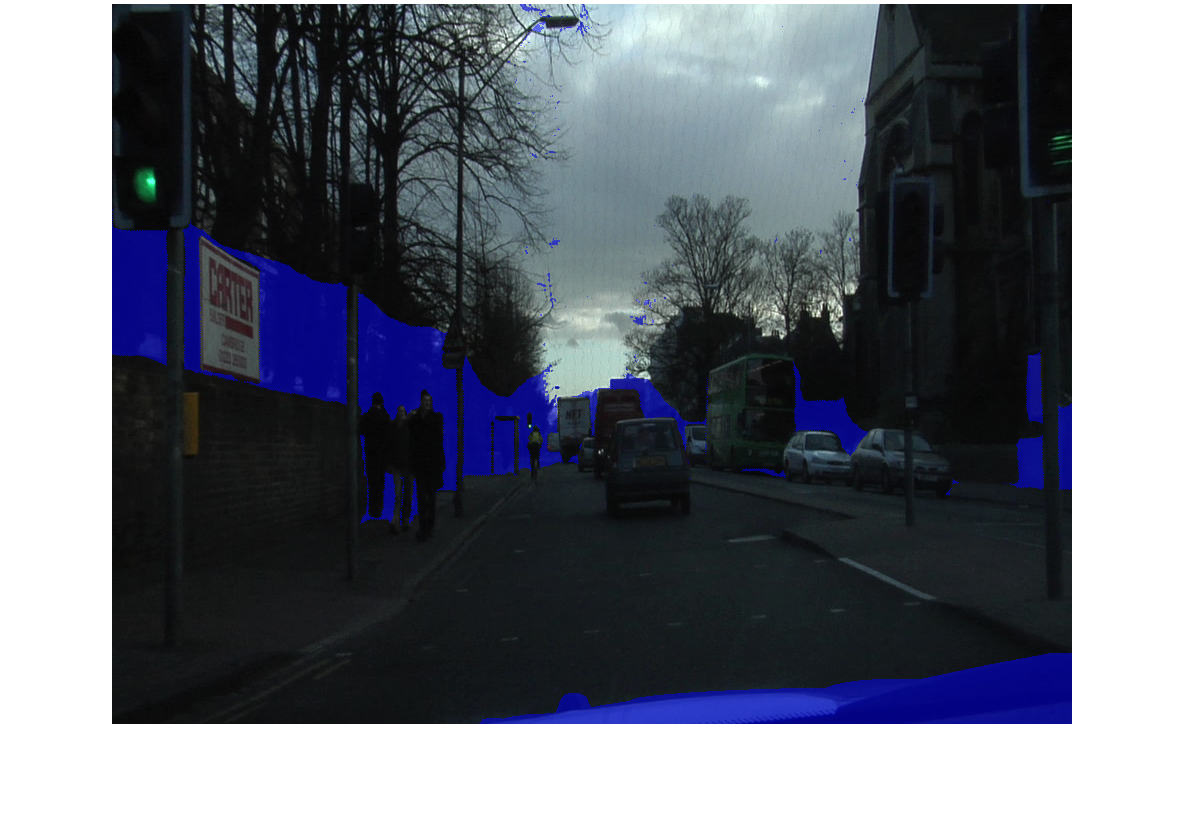

undefinedPixels = isundefined(C);
B = labeloverlay(I,undefinedPixels);
figure
imshow(B)
title('Undefined Pixel Labels')

**Clean up data (e.g., consolidating labels into fewer categories/classes)**

To make training easier, we will group the 32 original classes in CamVid to 11 classes, as follows:

classes = [
    "Sky"
    "Building"
    "Pole"
    "Road"
    "Pavement"
    "Tree"
    "SignSymbol"
    "Fence"
    "Car"
    "Pedestrian"
    "Bicyclist"
    ];

To reduce 32 classes into 11, multiple classes from the original dataset are grouped together. For example, "Car" is a combination of "Car", "SUVPickupTruck", "Truck_Bus", "Train", and "OtherMoving". 

Return the grouped label IDs by using the supporting function `camvidPixelLabelIDs`, which is listed at the end of this example.

labelIDs = camvidPixelLabelIDs();

Use the classes and label IDs to create the `pixelLabelDatastore.`

labelDir = fullfile(outputFolder,'labels');
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

Read the Mth pixel label image and display it on top of the image.

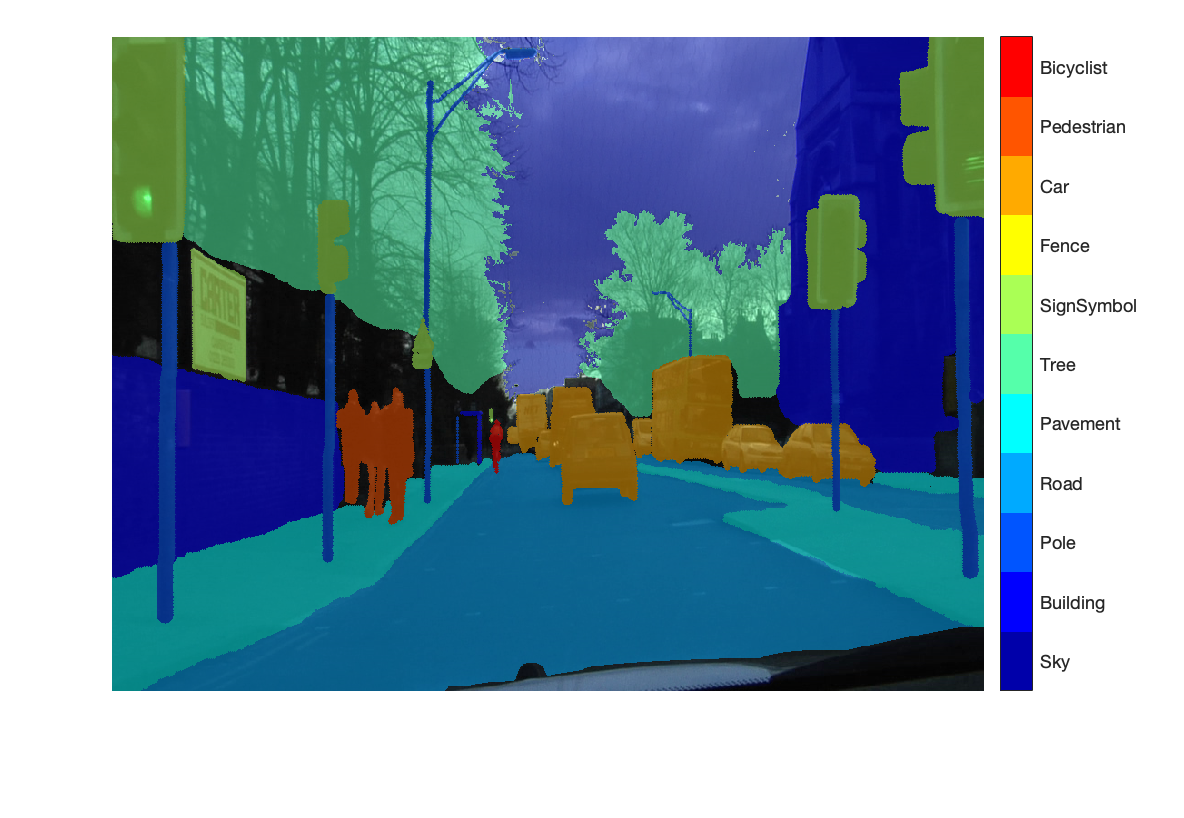

C = readimage(pxds,M);
cmap = jet(numel(classes));
B = labeloverlay(I,C,'Colormap',cmap);
figure
imshow(B)

% add colorbar
N = numel(classes);
ticks = 1/(N*2):1/N:1;
colorbar('TickLabels',cellstr(classes),'Ticks',ticks,'TickLength',0,'TickLabelInterpreter','none');
colormap(cmap)

The `pixelLabelDatastore` with the new class names can now be used to train a network for the 11 classes without having to modify the original CamVid pixel labels.

**Explore dataset properties/statistics**

To see the distribution of class labels in the CamVid dataset, use [ `countEachLabel`](docid:vision_ref.mw_1c600e69-1a15-4538-9629-7bceaafbd4e7). This function counts the number of pixels by class label.

tbl = countEachLabel(pxds)

tbl = 11×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________

    {'Sky'       }    7.6801e+07      4.8315e+08   
    {'Building'  }    1.1737e+08      4.8315e+08   
    {'Pole'      }    4.7987e+06      4.8315e+08   
    {'Road'      }    1.4054e+08      4.8453e+08   
    {'Pavement'  }    3.3614e+07      4.7209e+08   
    {'Tree'      }    5.4259e+07       4.479e+08   
    {'SignSymbol'}    5.2242e+06      4.6863e+08   
    {'Fence'     }    6.9211e+06       2.516e+08   
    {'Car'       }    2.4437e+07      4.8315e+08   
    {'Pedestrian'}    3.4029e+06      4.4444e+08   
    {'Bicyclist' }    2.5912e+06      2.6196e+08   


Visualize the pixel counts by class.

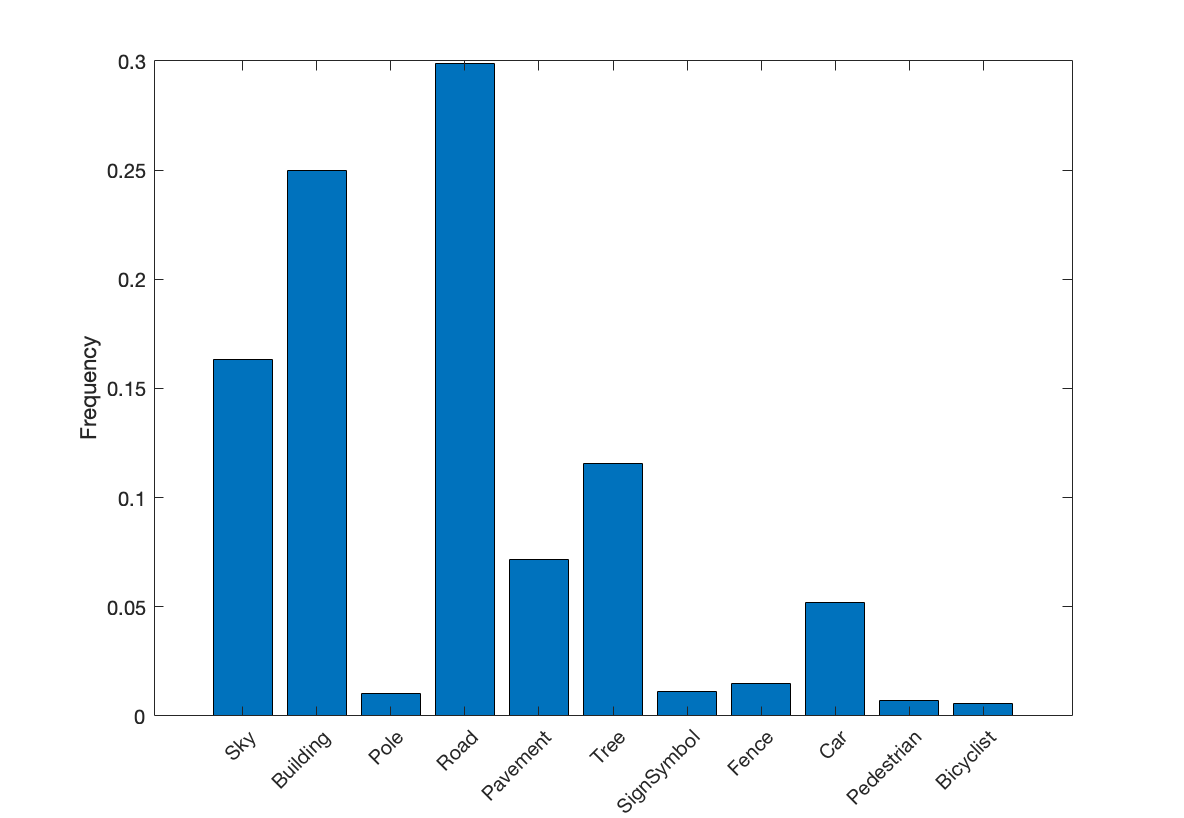

frequency = tbl.PixelCount/sum(tbl.PixelCount);
bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

**Prepare training, validation, and test sets**

Deeplab v3+ is trained using 60% of the images from the dataset. The rest of the images are split evenly in 20% and 20% for validation and testing respectively. The following code randomly splits the image and pixel label data into a training, validation and test set.

[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds);

The 60/20/20 split results in the following number of training, validation and test images:

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 421

numValImages = numel(imdsVal.Files)

numValImages = 140

numTestingImages = numel(imdsTest.Files)

numTestingImages = 140

#### Step 3: Create network.

**Download a pre-trained version of Deeplab v3+ network with weights initialized from a pre-trained Resnet-18 network**

pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/deeplabv3plusResnet18CamVid.mat';
pretrainedFolder = fullfile(tempdir,'pretrainedNetwork');
pretrainedNetwork = fullfile(pretrainedFolder,'deeplabv3plusResnet18CamVid.mat'); 
if ~exist(pretrainedNetwork,'file')
    mkdir(pretrainedFolder);
    disp('Downloading pretrained network (58 MB)...');
    websave(pretrainedNetwork,pretrainedURL);
end

**Create network**

% Specify the network image size. This is typically the same as the traing image sizes.
imageSize = [720 960 3];

% Specify the number of classes.
numClasses = numel(classes);

% Create DeepLab v3+.
lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet18");

**Balance classes using class weighting**

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.3182
    0.2082
    5.0924
    0.1744
    0.7103
    0.4175
    4.5371
    1.8386
    1.0000
    6.6059


Specify the class weights using a [ `pixelClassificationLayer`](docid:vision_ref.mw_783aebd8-1ff1-4bc6-8508-90c8b71fca32).

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

**Select training options**

% Define validation data.
pximdsVal = pixelLabelImageDatastore(imdsVal,pxdsVal);

% Define training options. 
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',pximdsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',8, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', tempdir, ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4);

**Configure **`imageDataAugmenter`** object to perform data augmentation**

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation',[-10 10],'RandYTranslation',[-10 10]);

#### Step 4: Train network

pximds = pixelLabelImageDatastore(imdsTrain,pxdsTrain, ...
    'DataAugmentation',augmenter);

Start training using [`trainNetwork`](docid:nnet_ref.bu6sn4c) if the `doTraining` flag is true. Otherwise, load a pretrained network.

doTraining = false;
if doTraining    
    [net, info] = trainNetwork(pximds,lgraph,options);
else
    data = load(pretrainedNetwork); 
    net = data.net;
end

#### Step 5: Evaluate results visually (displaying a test image and overlaying predicted labels)

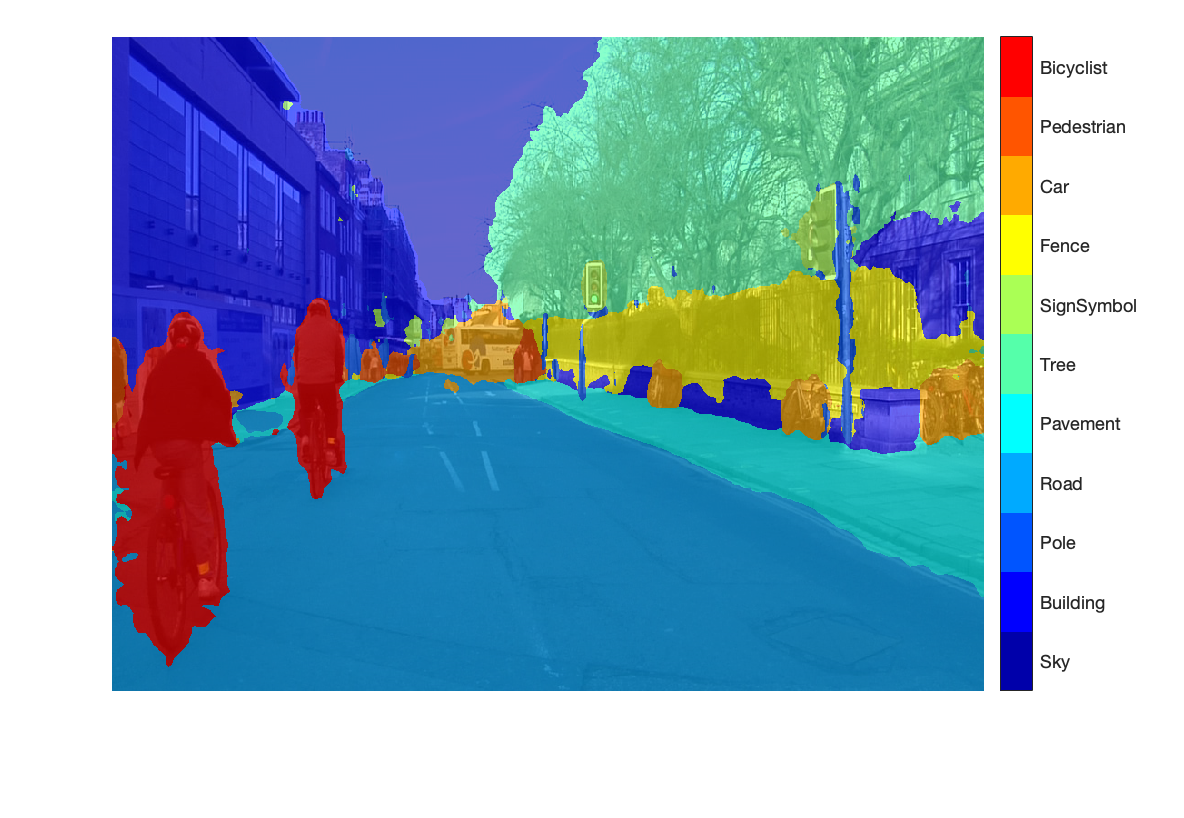

I = readimage(imdsTest,35);
C = semanticseg(I, net);

B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.4);
imshow(B)
pixelLabelColorbar(cmap, classes);

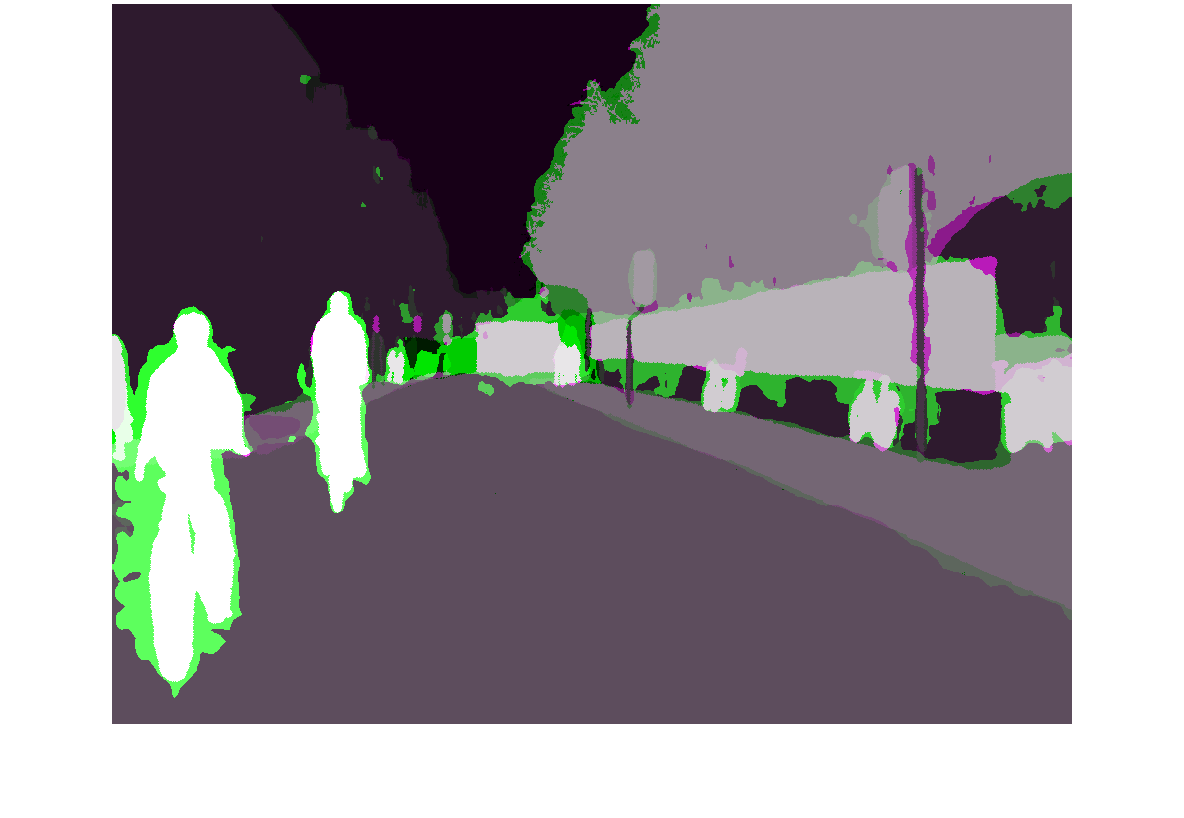


expectedResult = readimage(pxdsTest,35);
actual = uint8(C);
expected = uint8(expectedResult);
imshowpair(actual, expected)


iou = jaccard(C,expectedResult);
table(classes,iou)

ans = 11×2 table
      classes         iou  
    ____________    _______

    "Sky"           0.91837
    "Building"      0.84479
    "Pole"          0.31203
    "Road"          0.93698
    "Pavement"      0.82838
    "Tree"          0.89636
    "SignSymbol"    0.57644
    "Fence"         0.71046
    "Car"           0.66688
    "Pedestrian"    0.48417
    "Bicyclist"     0.68431


#### Step 6: Evaluate results quantitatively using different metrics (class accuracy, IoU)

pxdsResults = semanticseg(imdsTest,net, ...
    'MiniBatchSize',4, ...
    'WriteLocation',tempdir, ...
    'Verbose',false);

Running semantic segmentation network
-------------------------------------
* Processed 12 images.


metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);

metrics.NormalizedConfusionMatrix

ans = 11×11 table
                     Sky         Building       Pole          Road        Pavement        Tree       SignSymbol      Fence          Car        Pedestrian    Bicyclist 
                  __________    __________    _________    __________    __________    __________    __________    __________    __________    __________    __________

    Sky              0.93112      0.005814     0.013663     2.469e-06    6.4973e-08      0.046583     0.0022956    6.4973e-07    0.00052056    3.2486e-07    5.2628e-06
    Building       0.0070808       0.78453     0.075313     0.0001514

metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.87695          0.85392       0.6302       0.80851        0.65051  


metrics.ClassMetrics

ans = 11×3 table
                  Accuracy      IoU      MeanBFScore
                  ________    _______    ___________

    Sky           0.93112     0.90209       0.8952  
    Building      0.78453     0.76098      0.58511  
    Pole          0.71586     0.21477       0.5144  
    Road          0.93024     0.91465      0.76696  
    Pavement      0.88466     0.70571      0.70919  
    Tree          0.87377     0.76323      0.70875  
    SignSymbol    0.79358     0.39309      0.48302  
    Fence         0.81506     0.46484      0.48565  
    Car           0.90956     0.76799      0.69233  
    Pedestrian    0.87629      0.4366      0.60792  
    Bicyclist     0.87844     0.60829      0.55089  


#### Step 7: (OPTIONAL) Repeat steps 3 through 6 using different pretrained networks, training options, data augmentation options, and/or metrics. 

Hint: See example at [https://www.mathworks.com/help/vision/ref/deeplabv3pluslayers.html](https://www.mathworks.com/help/vision/ref/deeplabv3pluslayers.html) 

% ENTER YOUR CODE HERE
% ...
% ...

Go back to top

## Supporting Functions

function labelIDs = camvidPixelLabelIDs()
% Return the label IDs corresponding to each class.
%
% The CamVid dataset has 32 classes. Group them into 11 classes following
% the original SegNet training methodology [1].
%
% The 11 classes are:
%   "Sky" "Building", "Pole", "Road", "Pavement", "Tree", "SignSymbol",
%   "Fence", "Car", "Pedestrian",  and "Bicyclist".
%
% CamVid pixel label IDs are provided as RGB color values. Group them into
% 11 classes and return them as a cell array of M-by-3 matrices. The
% original CamVid class names are listed alongside each RGB value. Note
% that the Other/Void class are excluded below.
labelIDs = { ...
    
    % "Sky"
    [
    128 128 128; ... % "Sky"
    ]
    
    % "Building" 
    [
    000 128 064; ... % "Bridge"
    128 000 000; ... % "Building"
    064 192 000; ... % "Wall"
    064 000 064; ... % "Tunnel"
    192 000 128; ... % "Archway"
    ]
    
    % "Pole"
    [
    192 192 128; ... % "Column_Pole"
    000 000 064; ... % "TrafficCone"
    ]
    
    % Road
    [
    128 064 128; ... % "Road"
    128 000 192; ... % "LaneMkgsDriv"
    192 000 064; ... % "LaneMkgsNonDriv"
    ]
    
    % "Pavement"
    [
    000 000 192; ... % "Sidewalk" 
    064 192 128; ... % "ParkingBlock"
    128 128 192; ... % "RoadShoulder"
    ]
        
    % "Tree"
    [
    128 128 000; ... % "Tree"
    192 192 000; ... % "VegetationMisc"
    ]
    
    % "SignSymbol"
    [
    192 128 128; ... % "SignSymbol"
    128 128 064; ... % "Misc_Text"
    000 064 064; ... % "TrafficLight"
    ]
    
    % "Fence"
    [
    064 064 128; ... % "Fence"
    ]
    
    % "Car"
    [
    064 000 128; ... % "Car"
    064 128 192; ... % "SUVPickupTruck"
    192 128 192; ... % "Truck_Bus"
    192 064 128; ... % "Train"
    128 064 064; ... % "OtherMoving"
    ]
    
    % "Pedestrian"
    [
    064 064 000; ... % "Pedestrian"
    192 128 064; ... % "Child"
    064 000 192; ... % "CartLuggagePram"
    064 128 064; ... % "Animal"
    ]
    
    % "Bicyclist"
    [
    000 128 192; ... % "Bicyclist"
    192 000 192; ... % "MotorcycleScooter"
    ]
    
    };
end


function pixelLabelColorbar(cmap, classNames)
% Add a colorbar to the current axis. The colorbar is formatted
% to display the class names with the color.

colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classNames;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end

% function cmap = camvidColorMap()
% % Define the colormap used by CamVid dataset.
% 
% cmap = [
%     128 128 128   % Sky
%     128 0 0       % Building
%     192 192 192   % Pole
%     128 64 128    % Road
%     60 40 222     % Pavement
%     128 128 0     % Tree
%     192 128 128   % SignSymbol
%     64 64 128     % Fence
%     64 0 128      % Car
%     64 64 0       % Pedestrian
%     0 128 192     % Bicyclist
%     ];
% 
% % Normalize between [0 1].
% cmap = cmap ./ 255;
% end

function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = camvidPixelLabelIDs();

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end